# **Welcome to Deci**

**A fluid pipeline to analyze EEG Data with ease**

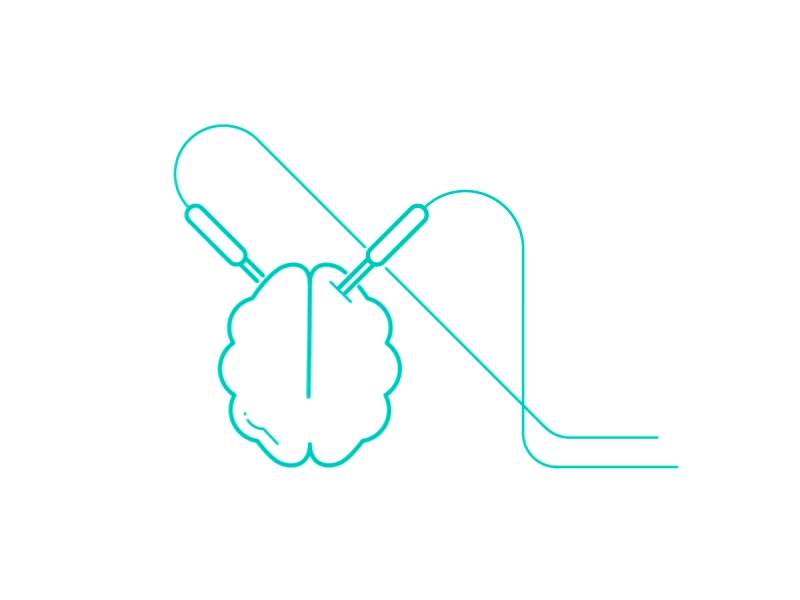

Written and Compiled by @John Nguyen of Robert Reinhart Lab on 10/15/2018, contact: Akida@bu.edu

## 0. MainMenu

Deci = [];
Deci.Folder.Raw         = ['C:\Users\User\Desktop\NE329\Module2_PD\RawData'];
Deci.SubjectList = 'gui';
Deci.Step               = 5;
Deci.Folder.Version     = ['C:\Users\User\Desktop\NE329\Module2_PD\ProcessedData'];
Deci.Retroactive  = true;

## 1. Trial Definitions

Deci.DT.Type = 'Simon_Polymerase';
Deci.DT.Starts     = {17};                                                                      % Cell Array of Markers for Start codes.
Deci.DT.Ends       = {18};                                                                      % Cell Array of Markers for End codes.
Deci.DT.Markers    = {[300 400] [31 34]};                                   % Cell Array of Markers for Trial Defs
Deci.DT.Locks      = [12 30 22];                                                                % Num Array for each timelock (usually Stim, Rsp and Fdb Onset )
Deci.DT.Toi        = [-.5 1.5];   

## 2. PreProcessing Steps

Deci.PP = [];
%Deci.PP.filter.bpfreq = [1 30];
%Deci.PP.filter.bpfilter = 'yes';

Deci.PP.ShowData = false;
Deci.ICA.do = true;

## 3. Artifact Rejection

Deci.Art.do = true;
Deci.Art.crittoilim = [-.5 1.5];
Deci.Art.Manual_Trial_Rejection = true;
Deci.Art.ShowArt = true;

## 4. Analysis

Deci.Analysis.Laplace       =false;                                                               % Uses Captrak .bvct file with same name in RawData Folder
Deci.Analysis.DownSample    = 500;

Deci.Analysis.Function = 'PD_Conflict';    
Deci.Analysis.Locks         = [2];                                                          % Which Lock to Analyze
Deci.Analysis.LocksTitle    = {'Rsp Onset'};                      % Folder Title to save each Lock as
Deci.Analysis.Conditions    = {[103,104] [101,102]};
Deci.Analysis.CondTitle     = {'Incorrect' 'Correct'};
Deci.Analysis.ERP.do  = true;

Deci.Analysis.Toilim = [-.5 1.5];
Deci.Analysis.Toi = [-.5 1.5];

## 5. Plotting

Deci is running retroactive subjects


ans = logical
   1


Running Deci for 18 subjects
 
----------------------
 
Plotting ERP
Loading Plottor for Subject #1: 8010_Session_1_PDDys_CC
the input is raw data with 1 channels and 18 trials
the call to "ft_appendtimelock" took 0 seconds
the input is raw data with 1 channels and 319 trials
the call to "ft_appendtimelock" took 0 seconds
Loading Plottor for Subject #2: 801_Session_1_PDDys_CC
the input is raw data with 1 channels and 38 trials
the call to "ft_appendtimelock" took 0 seconds
the input is raw data with 1 channels and 314 trials
the call to "ft_appendtimelock" took 0 seconds
Loading Plottor for Subject #3: 801_Session_2_PDDys_CC
the input is raw data with 1 channels and 39 trials
the call to "ft_appendtimelock" took 0 seconds
the input is raw data with 1 channels and 312 trials
the call to "ft_appendtimelock" took 0 seconds
Loading Plottor for Subject #4: 802_Session_1_PDDys_CC
the input is raw data with 1 channels and 14 trials
the call to "ft_appendtimelock" took 0 seconds
the input is r

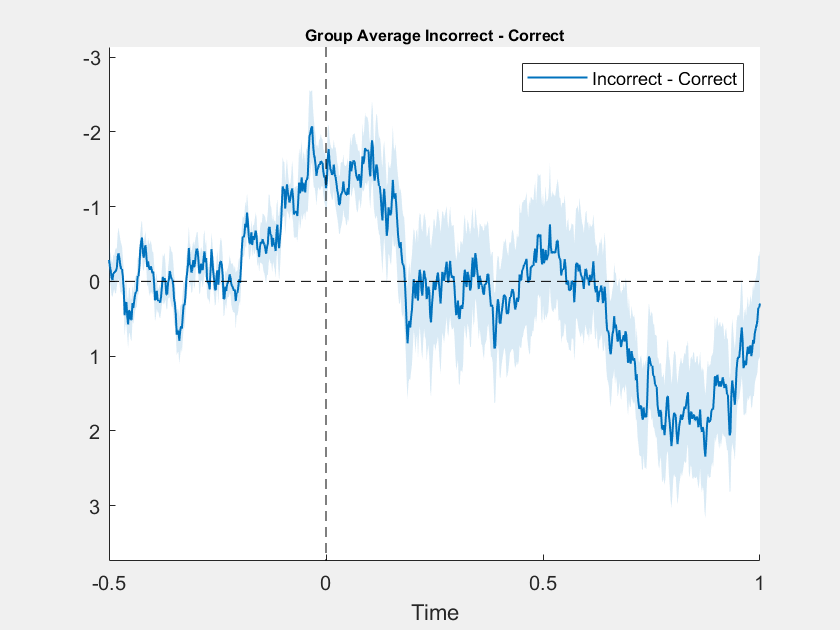

the call to "ft_singleplotER" took 0 seconds


Deci.Analysis.Version = [Deci.Folder.Version];
Deci.Plot.Figures      = [true true ];
Deci.Plot.Math         = {'x1 -x2'};           % Condition Math done after Bsl, Condition Indexes are appended on.
Deci.Plot.Draw         = {[1 2] [3] };                   % Cell array of Condition Index for each figure

Deci.Plot.Title        = {'Incorrect vs Correct' 'Incorrect - Correct'};          % Title for each figure
Deci.Plot.Subtitle     = {{'Incorrect' 'Correct'} {'Incorrect - Correct'} };     % Cell array of strings of subtitles for each Condition

Deci.Plot.BslRef = 'Rsp Onset';
Deci.Plot.Lock =   'Rsp Onset';
Deci.Plot.Bsl     = [-.5 -.2];



Deci.Run.ERP =true;
Deci.Plot.GrandAverage = true;

Deci.Plot.GroupLevel =  false;
Deci.Plot.Groups = {~[] logical([1 0 0 1 0 0 0 0 0 1 0 0 0 0 0 0 0 0])};
    

Deci.Plot.Topo.do    =false;
Deci.Plot.Topo.Toi     = [0 .2];                   % Time of Interest
Deci.Plot.Topo.Channel = ['PD-All'];                   % Channel of Interest

Deci.Plot.Wire.do    =true;
Deci.Plot.Wire.Channel =   {'FCz'};            % Channel of Interest
Deci.Plot.Wire.Toi     = [-.5 1.5];                   % Time of Interest

Deci.Plot.Bar.do    =false;
Deci.Plot.Bar.Toi     = [0 .2];                    % Time of Interest
Deci.Plot.Bar.Channel =  {'FCz'};            % Channel of Interest

Deci.Plot.Stat.do = false; % Will only work if for large subject pools
if Deci.Plot.Stat.do
    Deci.Plot.Stat.Type = 'Anova/T-test';
    Deci.Plot.Stat.alpha = .05;
    Deci.Plot.Stat.correctm = 'no';
end


Deci_Backend(Deci);